c1 = 0.5176;                          %value given
c2 = 116;                             %value given
c3 = 0.4;                             %value given
c4 = 5;                               %value given
c5 = 21;                              %value given
c6 = 0.0068;                          %value given
Beta = 0;                             % setting beta =0 degree
Lamda = linspace(0, 15, 100);         % Tip Speed Ratio 
R = 9;                                % Radius
r = 1.2;                              % Air Density
A = pi * R^2;                         % Turbine Sweep Area 
wind = 5:1:12;                        % Wind Speed (Constant)
maxPower = 0;                         % For ploting max power point 
optimalSpeed = 0; %                   For ploing max power point

figure;
hold on;

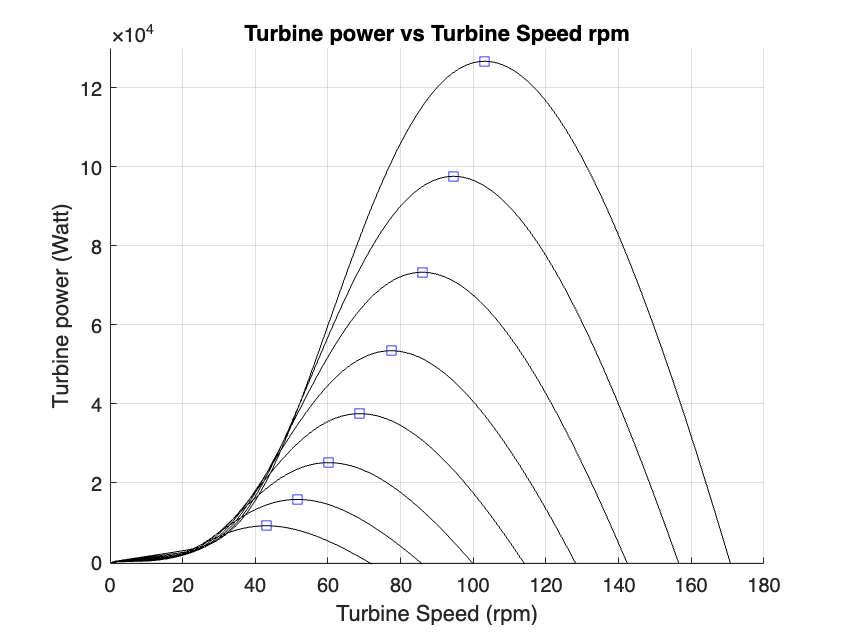

for w = wind
    S1_values = [];
    P_values = [];
    for Lamda_val = 0:0.1:15
        T = 1 / (Lamda_val + 0.08 * Beta) - (0.035 / (Beta^3 + 1));    %Power Coefficient
        Cp = c1 * (c2 * T - c3 * Beta - c4) * exp(-c5 * T) + c6 * Lamda_val;
        S1 = ((Lamda_val * w) / (2 * pi * R)) * 60;                    %Calculate Turbie Speed 
        P = Cp * 0.5 * r * A * w^3;                                    %Calculate Power

        S1_values = [S1_values S1];
        P_values = [P_values P];
    end
    
                                                           % Plot S1 vs P for each wind value
    plot(S1_values, P_values,'black', 'DisplayName', ['Wind: ' num2str(w) 'm/s']);
    
                                         % Find the maximum power and its corresponding speed
    [maxP, maxIndex] = max(P_values);
    if maxP > maxPower
        maxPower = maxP;
        optimalSpeed = S1_values(maxIndex);
        plot(optimalSpeed, maxPower, 'bs', 'DisplayName', 'Max Power');
    end
end

grid on;
xlabel('Turbine Speed (rpm)');
ylabel('Turbine power (Watt)');
title('Turbine power vs Turbine Speed rpm');
ylim([-500 130000])